# Gaussian fitting in 2D

The decay of the auto-correlation function, either in time (1D) or in space (2D), tends to have a Gaussian shape. Once the 2D correlation functions are calculated, they are fitted to a Gaussian inside the STICS code. 

## Gaussian function

*Based on *[***Gaussian function***](https://en.wikipedia.org/wiki/Gaussian_function) 

The Gaussian function has the form


$$f(x) = a \cdot exp  \left ( - \frac{ (x-b)^2 }{2c^2} \right)$$


for arbitrary real constants *a*, *b* and non-zero *c*. The parameter *a* is the height of the curve's peak, *b* is the position of the center of the peak and *c* (the standard deviation, sometimes called the Gaussian RMS width) controls the width of the "bell".

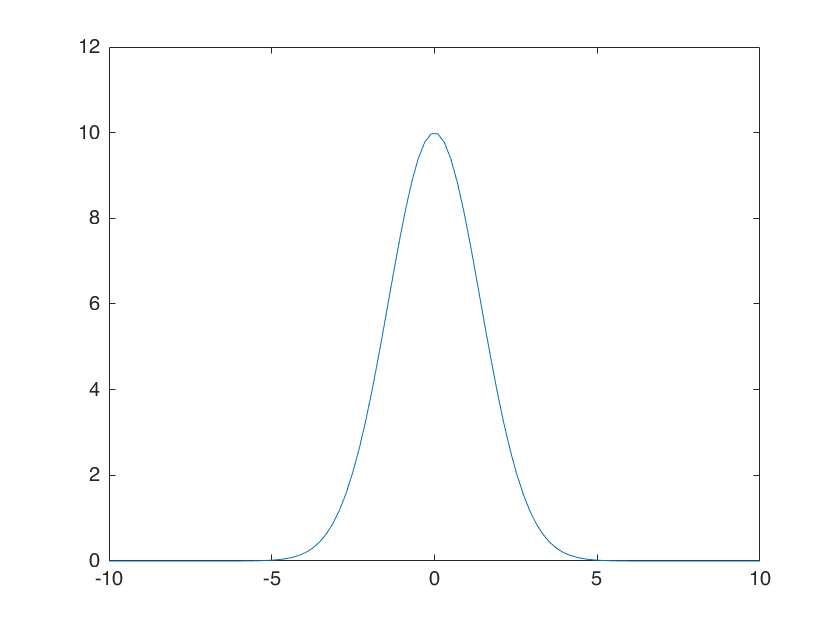

a =10;
b =0;
c = 1;
N = 10.0; 
x = linspace(-N, N);
f = a * exp(-((x-b).^2)/(2*c).^2);
figure;
plot(x,f); ylim([0, a+2]);

In 2D, we have:


$$f(x,y)=a\cdot \exp \left ( -\left (\frac{(x-x_{0})^2}{2\sigma^2_{X}} + \frac{(y-y_{0})^2}{2\sigma_{Y}^2} \right )\right )$$


Where A is the amplitude, $x_{0}$ and $y_{0}$ are the center coordinates and $\sigma_{X}$ and $\sigma_{Y}$ are the $x$ and $y$ spreads of the Gaussian. 

figure;
N = 10.0; a = 
x = linspace(-N, N);
y = x;
[X,Y] = meshgrid(x,y);
X0 = 0; Y0 = 0;
Sx = 3;
Sy = 3;
Z = (a.*exp(-(((X-X0).^2)/(2*Sx.^2) + ((Y-Y0).^2)/(2*Sy.^2))));

Unrecognized function or variable 'a'.

surf(X,Y,Z);
shading interp

The Gaussian fitting step outputs the `coeffGtime` variable:

% load('C:\Users\malvi\OneDrive - McGill University\Data\Hayer\210108\STICSOutputs\210108-2-3-MYL9_reg_205px-ROI6\VelocityMap210108-2-3-MYL9_reg_205px-ROI6_32x4_5x1_t100r32o32v5.mat');
% k = 45; u = 1; i = 1; j =1; 
velocityMap{k}.coeffGtime{i,j}

ans =     0.0090    0.4666    0.4666   -0.0005    0.0550    0.0550
    0.0083    0.4906    0.4906   -0.0005   -0.0259    0.0623
    0.0077    0.5166    0.5166   -0.0005   -0.1024    0.0488
    0.0064    0.5387    0.5387   -0.0005   -0.1754    0.0448


in which the first column corresponds to the Gaussian amplitude, the second and third correspond to the width of the peak in $x$ and $y$, the fourth corresponds to the offset and the fifth and sixth columnd are the peak coordinates in $x$ and $y$.

By pluggin in the fitted values from `coeffGtime`, we can reconstruct the Gaussian:

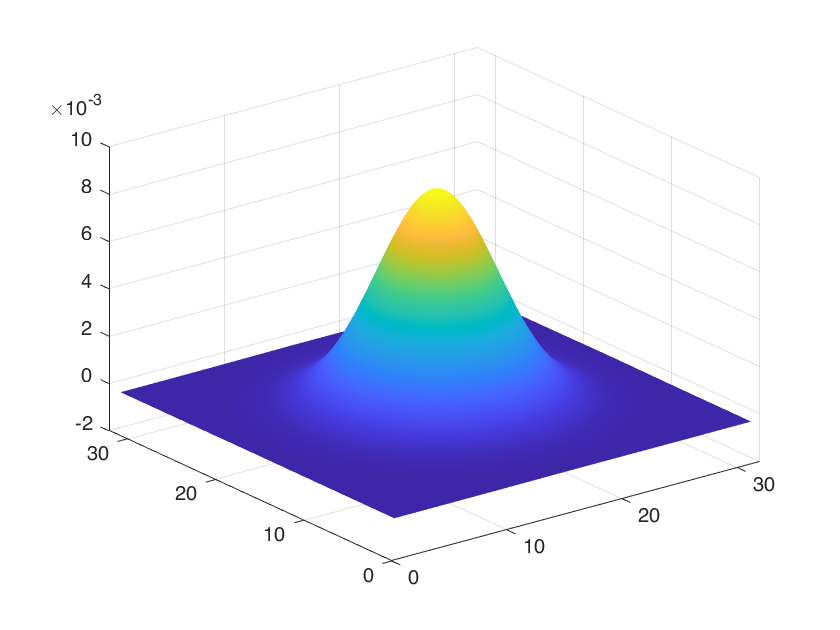

figure;
% x = linspace(opt.ROIsize/2 - opt.ROIsize/8, opt.ROIsize/2 + opt.ROIsize/8);
x = linspace(1, opt.ROIsize);
y = x;
[X,Y] = meshgrid(x,y);
tau = 0;
a = velocityMap{k}.coeffGtime{i,j}(tau+1,1);
Sx = velocityMap{k}.coeffGtime{i,j}(tau+1,2)/opt.pixelSize;
Sy = velocityMap{k}.coeffGtime{i,j}(tau+1,3)/opt.pixelSize;
Offset = velocityMap{k}.coeffGtime{i,j}(tau+1,4);
X0 = velocityMap{k}.coeffGtime{i,j}(tau+1,5) + (opt.ROIsize/2) + 1;
Y0 = velocityMap{k}.coeffGtime{i,j}(tau+1,6) + (opt.ROIsize/2) + 1;
Z = a.*exp(-(((X-X0).^2)/(2*Sx.^2) + ((Y-Y0).^2)/(2*Sy.^2))) + Offset;
surf(X,Y,Z);
% mesh(X, Y, z);
shading interp

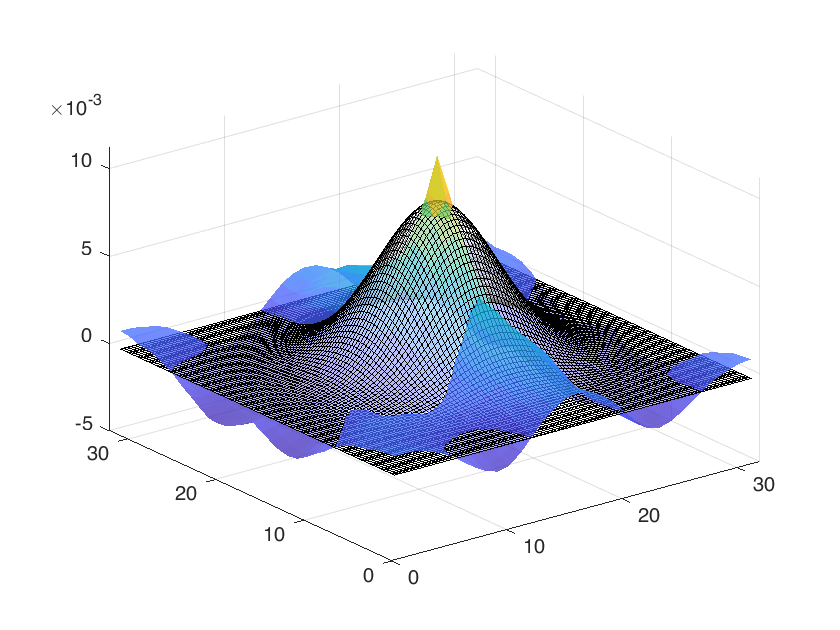

s = surf(corrfn(:,:,tau+1));

s.EdgeColor = 'none';
s.FaceAlpha = 0.75;
hold on;
m = mesh(X, Y, Z);
m.EdgeColor = [0 0 0];
m.FaceAlpha = 0.5;
hold off;


[coeffGtime] = gaussfit(corrfn,'time',opt.pixelSize,'n',opt.fitRadius)

coeffGtime =     0.0090    0.4666    0.4666   -0.0005    0.0550    0.0550
    0.0083    0.4906    0.4906   -0.0005   -0.0259    0.0623
    0.0077    0.5166    0.5166   -0.0005   -0.1024    0.0488
    0.0064    0.5387    0.5387   -0.0005   -0.1754    0.0448


[coeffGtimeAsym] = gaussfit(corrfn,'timeasym',opt.pixelSize,'n',opt.fitRadius)

coeffGtimeAsym =     0.0077    0.3778    1.2400   -0.0009    0.0549    0.0495
    0.0074    0.3835    1.2999   -0.0009   -0.0263    0.0506
    0.0070    0.3946    1.4047   -0.0009   -0.1155    0.0373
    0.0058    0.4165    1.4535   -0.0008   -0.1976    0.0265


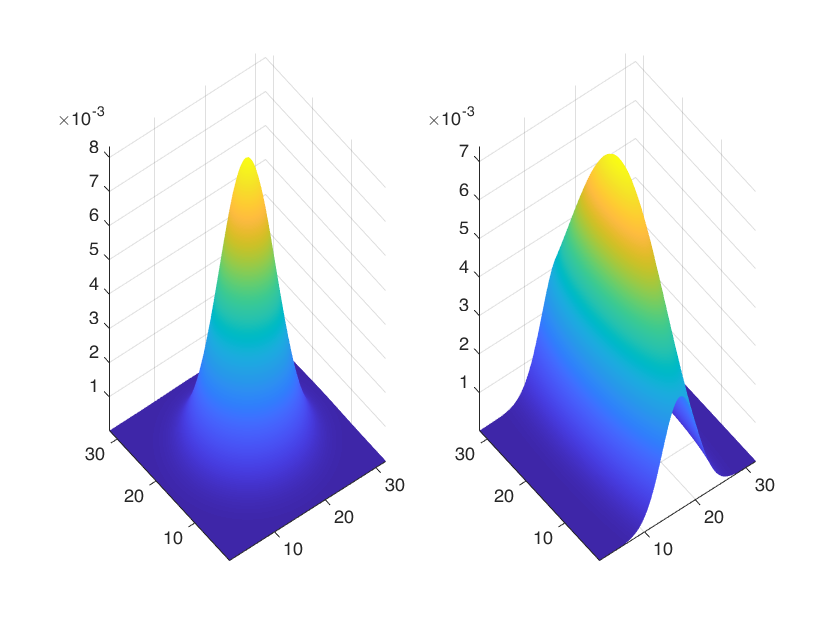

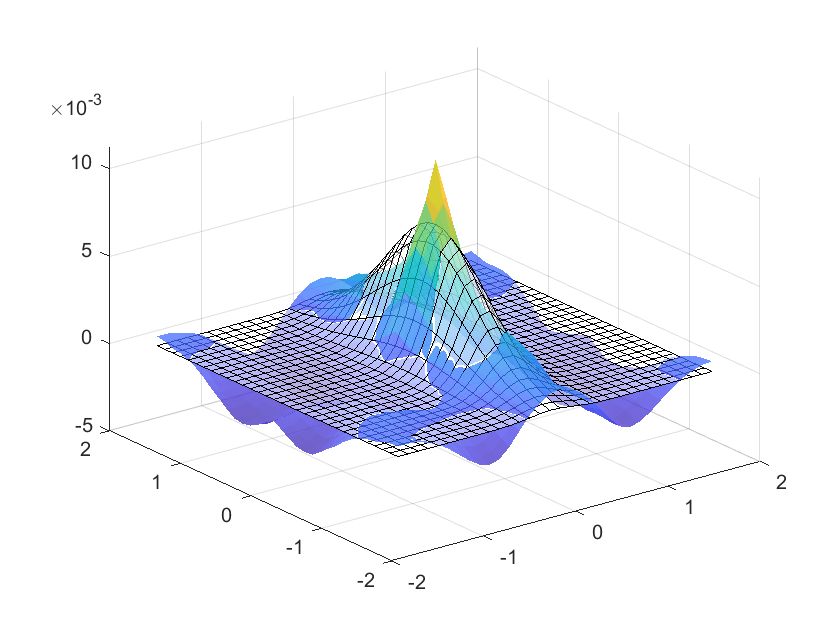

figure;
subplot(1,2,1);

% x = linspace(opt.ROIsize/2 - opt.ROIsize/8, opt.ROIsize/2 + opt.ROIsize/8);
x = linspace(1, opt.ROIsize);
y=x;
[X,Y]=meshgrid(x,y);
a = coeffGtime(2,1);
Sx = coeffGtime(2,2)/opt.pixelSize;
Sy = coeffGtime(2,3)/opt.pixelSize;
Offset = coeffGtime(2,4);
X0 = coeffGtime(2,5) + (opt.ROIsize/2) + 1;
Y0 = coeffGtime(2,6) + (opt.ROIsize/2) + 1;
z = a.*exp(-( ((X-X0).^2)/(2*Sx.^2)  +  ((Y-Y0).^2)/(2*Sy.^2) ) );% + Offset;
surf(X,Y,z);
% mesh(X, Y, z);
shading interp
axis tight

subplot(1,2,2);
N = opt.ROIsize;
% x = linspace(opt.ROIsize/2 - opt.ROIsize/8, opt.ROIsize/2 + opt.ROIsize/8);
x = linspace(1, opt.ROIsize);
y = x;
[X,Y]=meshgrid(x,y);
a = coeffGtimeAsym(2,1);
Sx = coeffGtimeAsym(2,2)/opt.pixelSize;
Sy = coeffGtimeAsym(2,3)/opt.pixelSize;
Offset = coeffGtimeAsym(2,4);
X0 = coeffGtimeAsym(2,5)  + (opt.ROIsize/2) + 1;
Y0 = coeffGtimeAsym(2,6) + (opt.ROIsize/2) + 1;
z = a.*exp(-( ((X-X0).^2)/(2*Sx.^2)  +  ((Y-Y0).^2)/(2*Sy.^2) ) );% + Offset;
surf(X,Y,z);
% mesh(X, Y, z);
shading interp
axis tight
hold off;

e = sqrt(1-(2*coeffGtime(1,2))^2/(2*coeffGtime(1,3))^2)

e = 0

e = sqrt(1-(2*coeffGtimeAsym(1,2))^2/(2*coeffGtimeAsym(1,3))^2)

e = 0.9525

## Changing the angle

In general, a two-dimensional elliptical Gaussian function is expressed as


$${f(x,y)=A\exp \left(-\left(a(x-x_{o})^{2}+2b(x-x_{o})(y-y_{o})+c(y-y_{o})^{2}\right)\right)}$$


For the general form of the equation the coefficient $A$ is the height of the peak and $(x_{o},y_{o})$is the center of the blob. 

If we set


$$a = {\frac {\cos ^{2}\theta}{2\sigma_{X}^2}}+{\frac {\sin^2\theta}{2\sigma_{Y}^2}}$$



$$b = -{\frac{\sin 2\theta}{4\sigma_{X}^2}}+{\frac {\sin 2\theta} {4\sigma _{Y}^2}}$$



$$c = {\frac{\sin ^2\theta}{2\sigma_{X}^2}}+{\frac {\cos^2\theta}{2\sigma_{Y}^2}}$$$


then we rotate the blob by a clockwise angle $\theta$ (for counterclockwise rotation invert the signs in the $b$ coefficient).

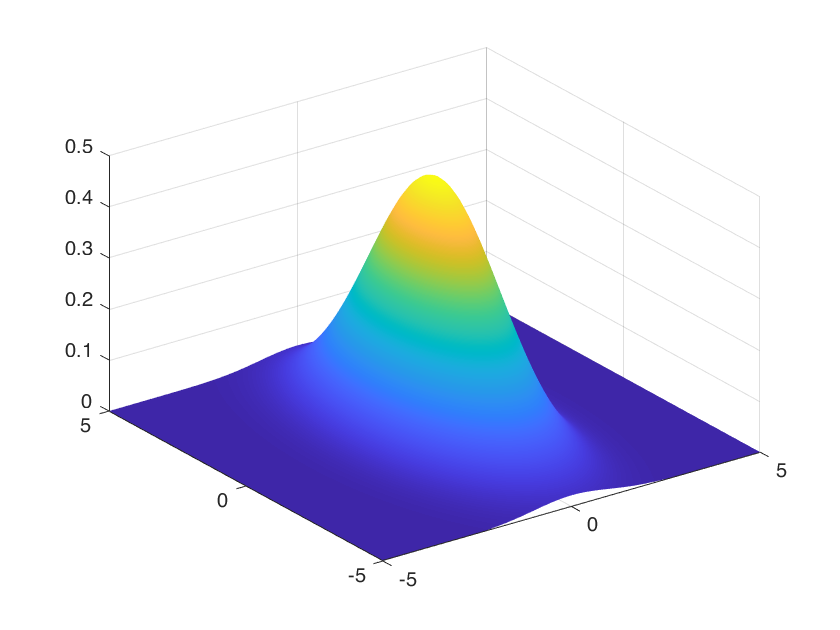

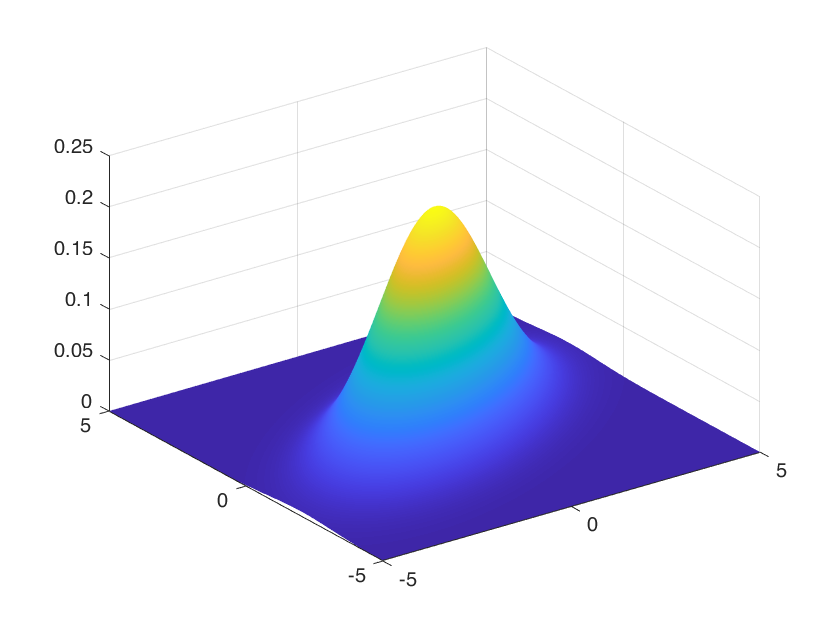

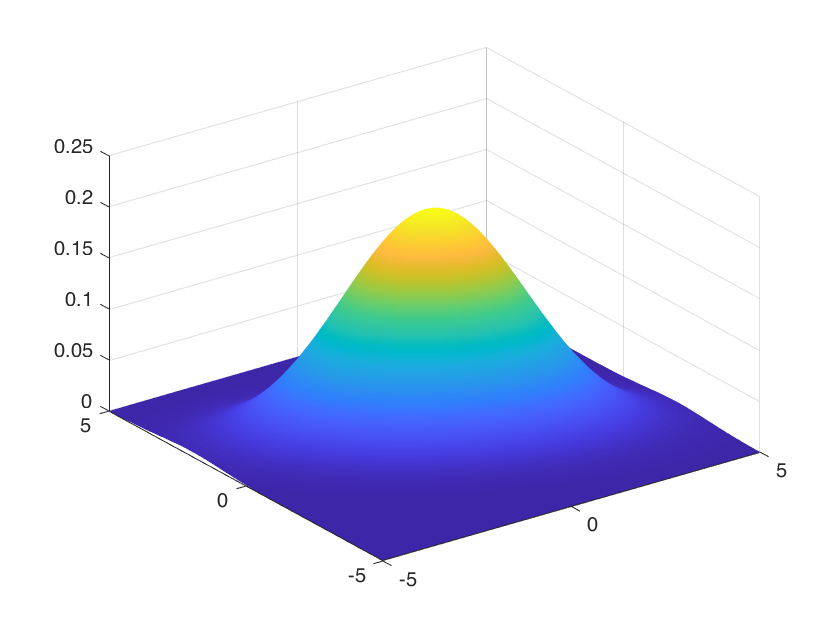

a = 1;
X0 = 0; Y0 = 0;

sigma_X = 1;
sigma_Y = 2;

[X, Y] = meshgrid(-5:.1:5, -5:.1:5);

for theta = 0:pi/3:pi
    figure;
    a = cos(theta)^2/(2*sigma_X^2) + sin(theta)^2/(2*sigma_Y^2);
    b = -sin(2*theta)/(4*sigma_X^2) + sin(2*theta)/(4*sigma_Y^2);
    c = sin(theta)^2/(2*sigma_X^2) + cos(theta)^2/(2*sigma_Y^2);

    Z = a*exp(- (a*(X-X0).^2 + 2*b*(X-X0).*(Y-Y0) + c*(Y-Y0).^2));
    surf(X,Y,Z);shading interp;view(-36,36)
end

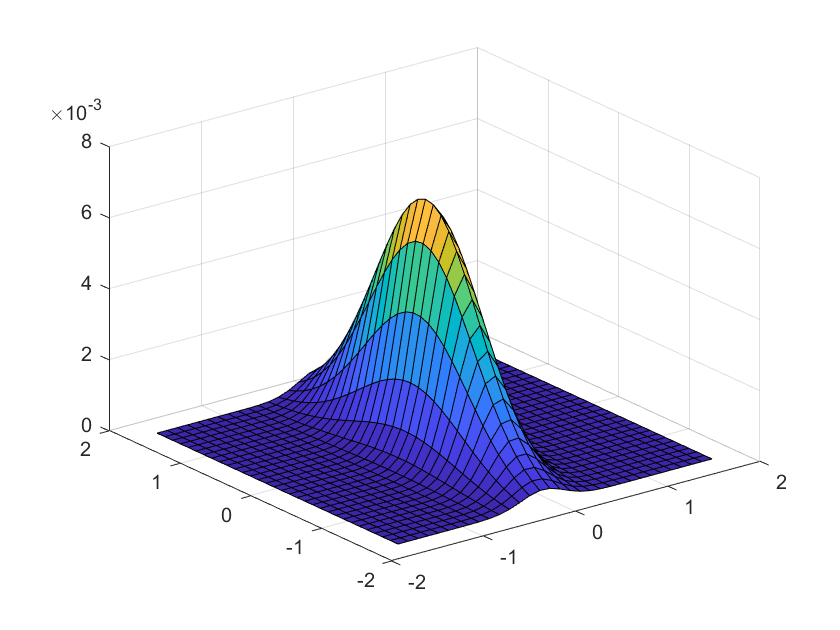

A = a(2,:);
Z = A(1)*exp( -(...
    ( mg(:,:,1)*cos(A(7))-mg(:,:,2)*sin(A(7)) - A(5)*cos(A(7))+A(6)*sin(A(7)) ).^2/(2*A(2)^2) + ... 
    ( mg(:,:,1)*sin(A(7))+mg(:,:,2)*cos(A(7)) - A(5)*sin(A(7))-A(6)*cos(A(7)) ).^2/(2*A(3)^2) ) );
surf(X,Y,Z);

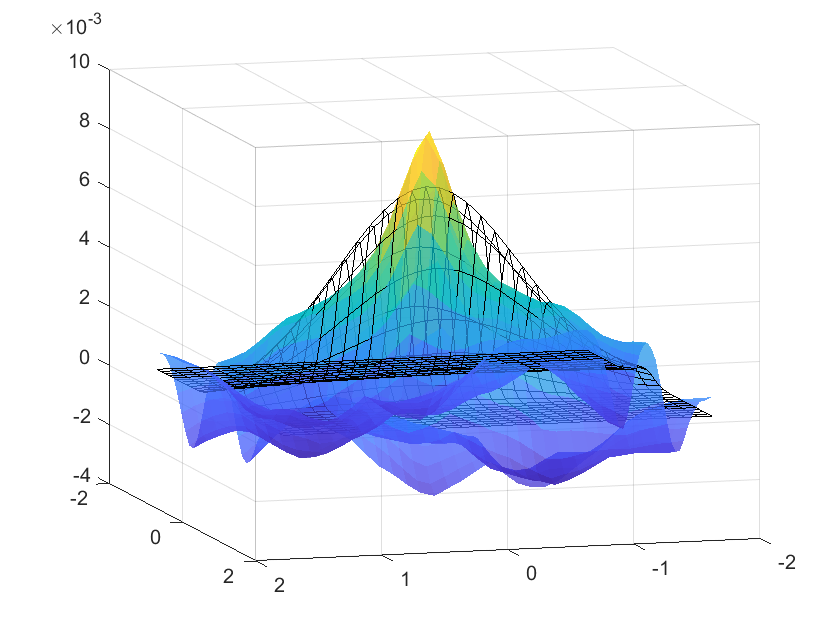

figure;
s = surf(X, Y, corrfn(:,:,2));
s.EdgeColor = 'none';
s.FaceAlpha = 0.75;
hold on;
m = mesh(X, Y, Z);
m.EdgeColor = [0 0 0];
m.FaceAlpha = 0;
hold off;

# Next steps:

- Calculate the goodness of fit of the straight line from the center of the fitted peaks. Include the $R^{2}$ as part of the metric by doing $SR\cdot R^2$.

- Show the straight line over the peak center coordinates. Determine a threshold for linear fit vs non-linear data.

- Fit an oblique Gaussian to the first ICF (ACF). 

- Extract the eccentricity and the angle $\theta$.

- Use the eccentricity to detect the shape of the features. Establish a threshold to distinguish puncta vs fibers.

- Plot the eccentricity over a mixed region. Show also the goodness of fit metric for different conditions. Puncta and fibers should have both different shapes and different spatiotemporal dynamics, although I believe tha shape qill be more informative.

- Acquire more data with higher temporal resolution and single-sites.